# Equlibrium analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

cmap_temp = [[0 0.4470 0.7410];[0.8500 0.3250 0.0980];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560]];

## Part 0: Initialization

### Create color map

Green color map v1

cmap_green = uint8([[247,252,245];[229,245,224];[199,233,192];[161,217,155];[116,196,118];[65,171,93];[35,139,69];[0,109,44];[0,68,27]]);

old_stepNum = size(cmap_green,1);
new_stepNum = 256;

cmap_green_1 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,1)),linspace(0,1,new_stepNum));
cmap_green_2 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,2)),linspace(0,1,new_stepNum));
cmap_green_3 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,3)),linspace(0,1,new_stepNum));

cmap_green_new = [cmap_green_1' cmap_green_2' cmap_green_3']/256;

Green color map v2

cmap_green_v2 = [[247,252,253];[229,245,249];[204,236,230];[153,216,201];[102,194,164];[65,174,118];[35,139,69];[0,109,44];[0,68,27]];

old_stepNum = size(cmap_green_v2,1);
new_stepNum = 256;

cmap_green_1_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,1)),linspace(0,1,new_stepNum));
cmap_green_2_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,2)),linspace(0,1,new_stepNum));
cmap_green_3_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,3)),linspace(0,1,new_stepNum));

cmap_green_new_v2 = [cmap_green_1_v2' cmap_green_2_v2' cmap_green_3_v2']/256;

Red color map v1

cmap_red = [[255,255,229];[255,247,188];[254,227,145];[254,196,79];[254,153,41];[236,112,20];[204,76,2];[153,52,4];[102,37,6]];

old_stepNum = size(cmap_red,1);
new_stepNum = 256;

cmap_red_1 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,1)),linspace(0,1,new_stepNum));
cmap_red_2 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,2)),linspace(0,1,new_stepNum));
cmap_red_3 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,3)),linspace(0,1,new_stepNum));

cmap_red_new = [cmap_red_1' cmap_red_2' cmap_red_3']/256;

### Color for lines

color_green = [38 143 75]/256;
color_red = [209 82 5]/256;

left_color = color_green;
right_color = color_red;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/combined_data'];

% Make result path
ResultPath = ['./result/combined_data'];

mkdir(FigPath)

mkdir(ResultPath)

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to the analyzed data
LoadDataPath =  ResultPath + "/CompiledData.mat"; 

load(LoadDataPath)

## Part 2: Plot average data

### Plot temporal dynamics for each bin

% binRange = 7:19;
% 
% for i = 1:length(binRange)
%     
%     bin_plot = binRange(i);
%     
%     AvrBinProteinFig = figure;  
%     %protein_err_plot = [protein_err(bin_plot,:) ]
%     set(AvrBinProteinFig,'defaultAxesColorOrder',[left_color; right_color]);
%     
%     yyaxis left
%     boundedline(timeFinal, nuclearFluoAPCombined(bin_plot,:),nuclearFluoAPErrCombined(bin_plot,:), '-','nan', 'gap','alpha','cmap', left_color);
%     ylabel('Protein (AU)')
%     %ylim([1E5 7.5E5])
%     ylim([0 11E5])
%     
%     yyaxis right
%     boundedline(timeFinal, spotFluoAPCombined(bin_plot,:),spotFluoAPErrCombined(bin_plot,:), '-','nan', 'gap','alpha','cmap', right_color);
%     ylim([0 1.9E5])
%     ylabel('Mean Transcriptional Activity (AU)')
%     xlim([0 35])
%     
%     pbaspect([2 1 1])
%     xlabel('Time (min)')
% end

### Plot for specific timepoints

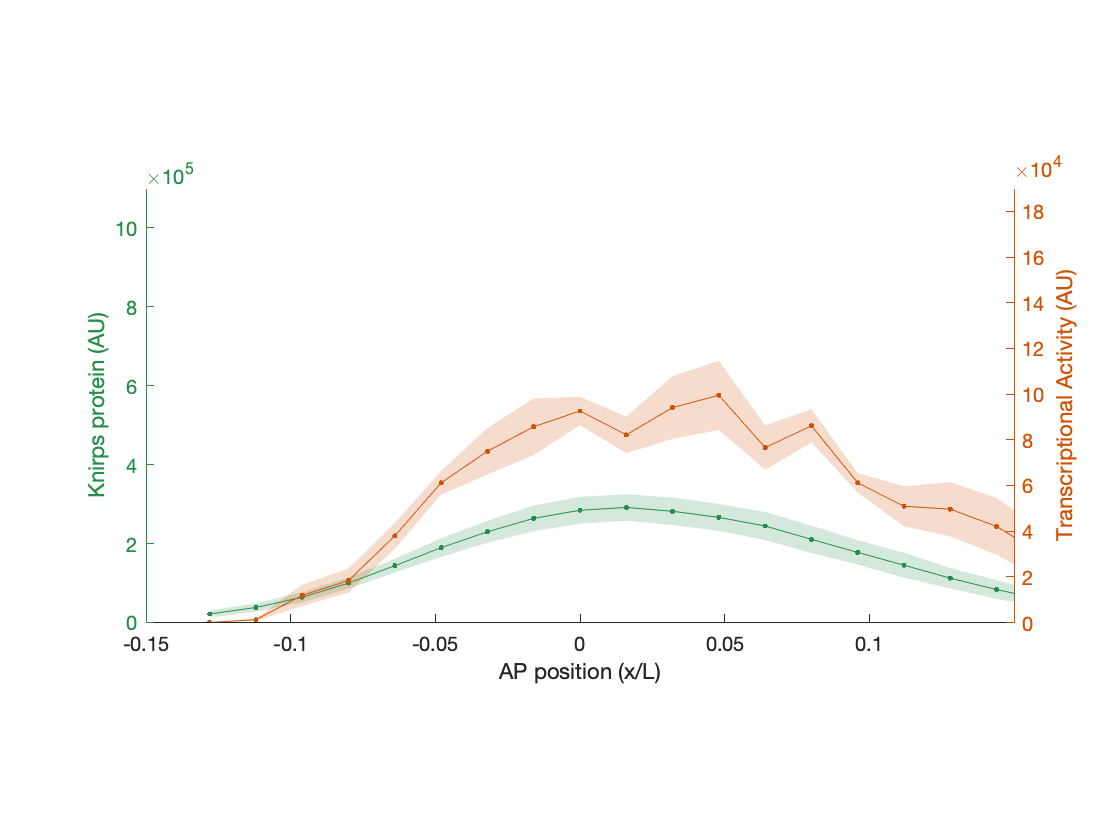

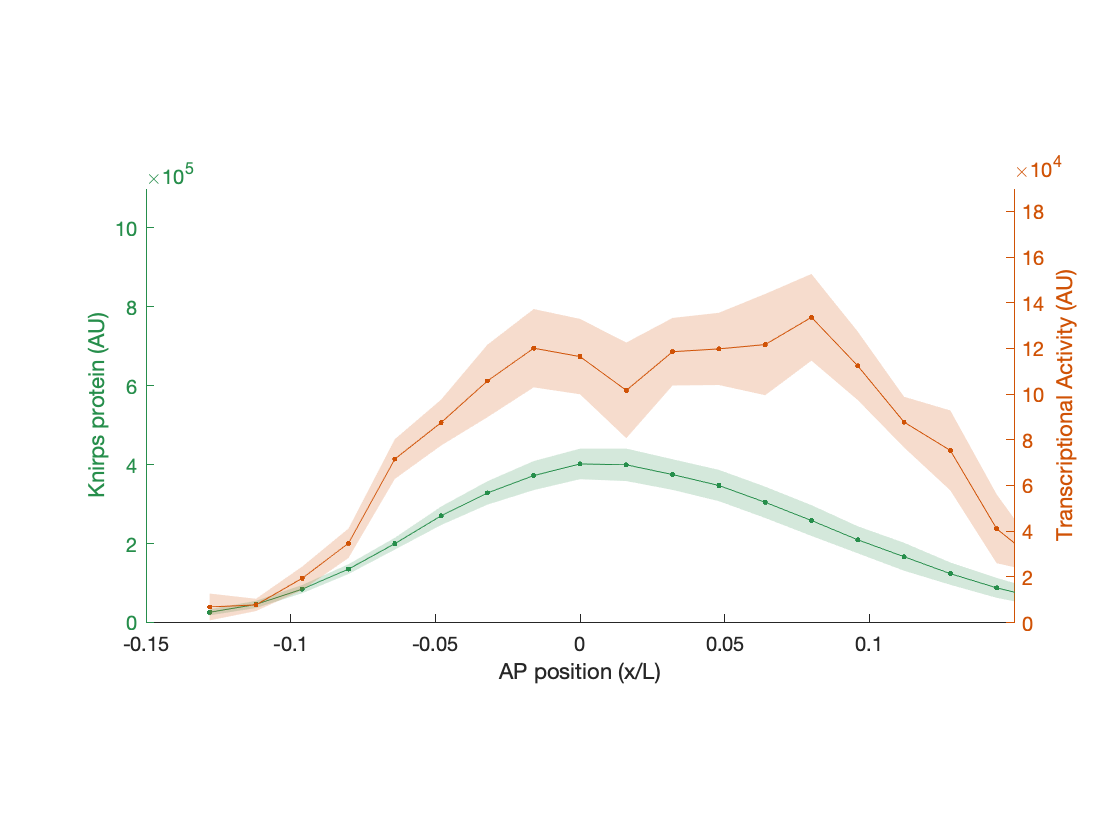

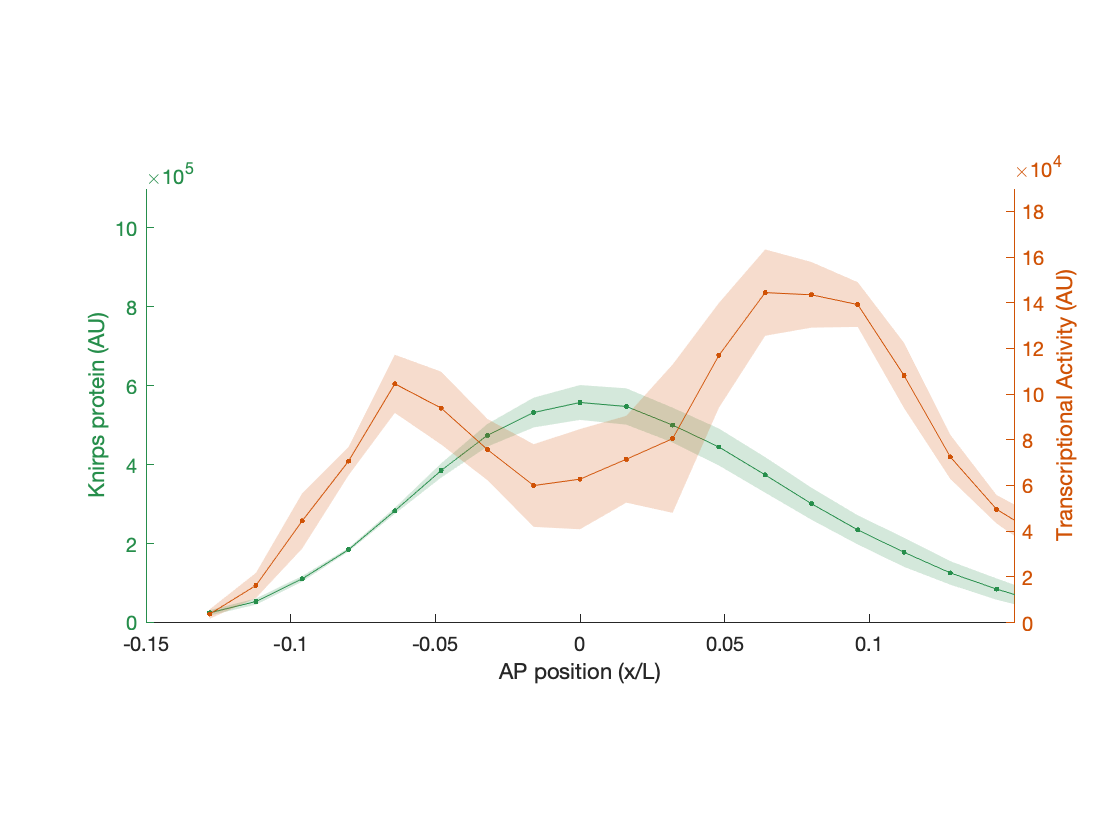

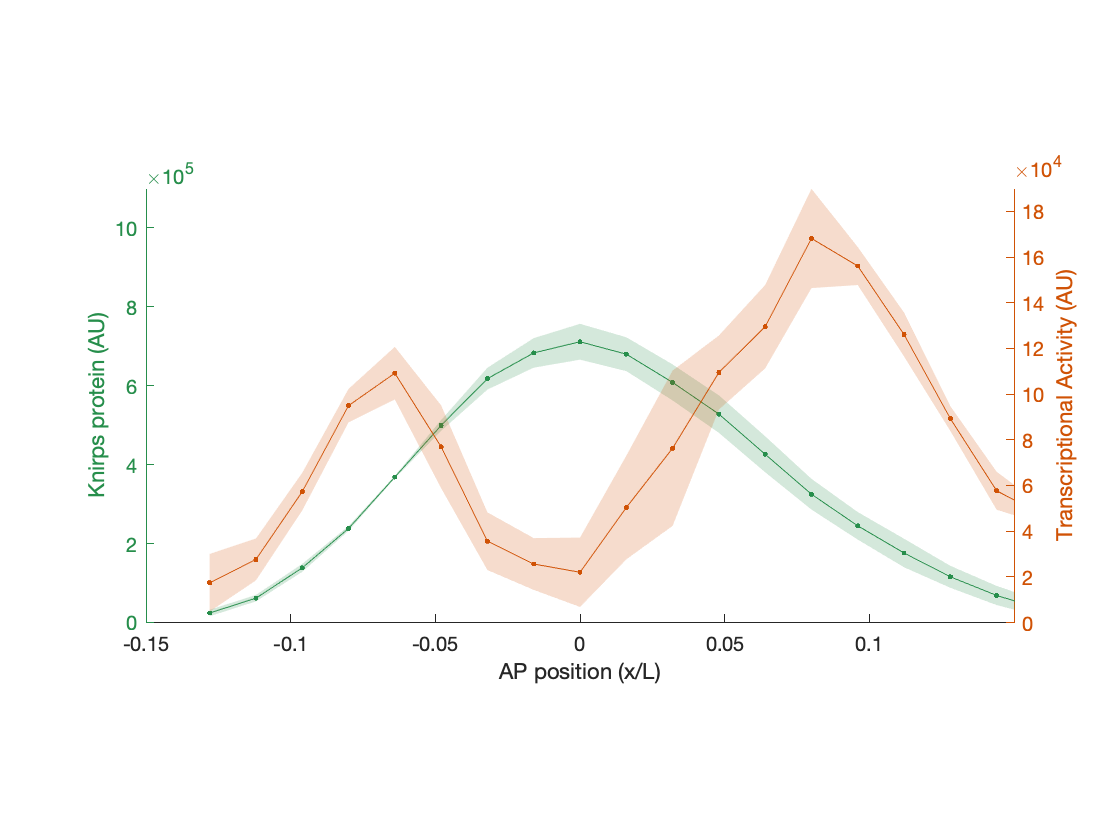

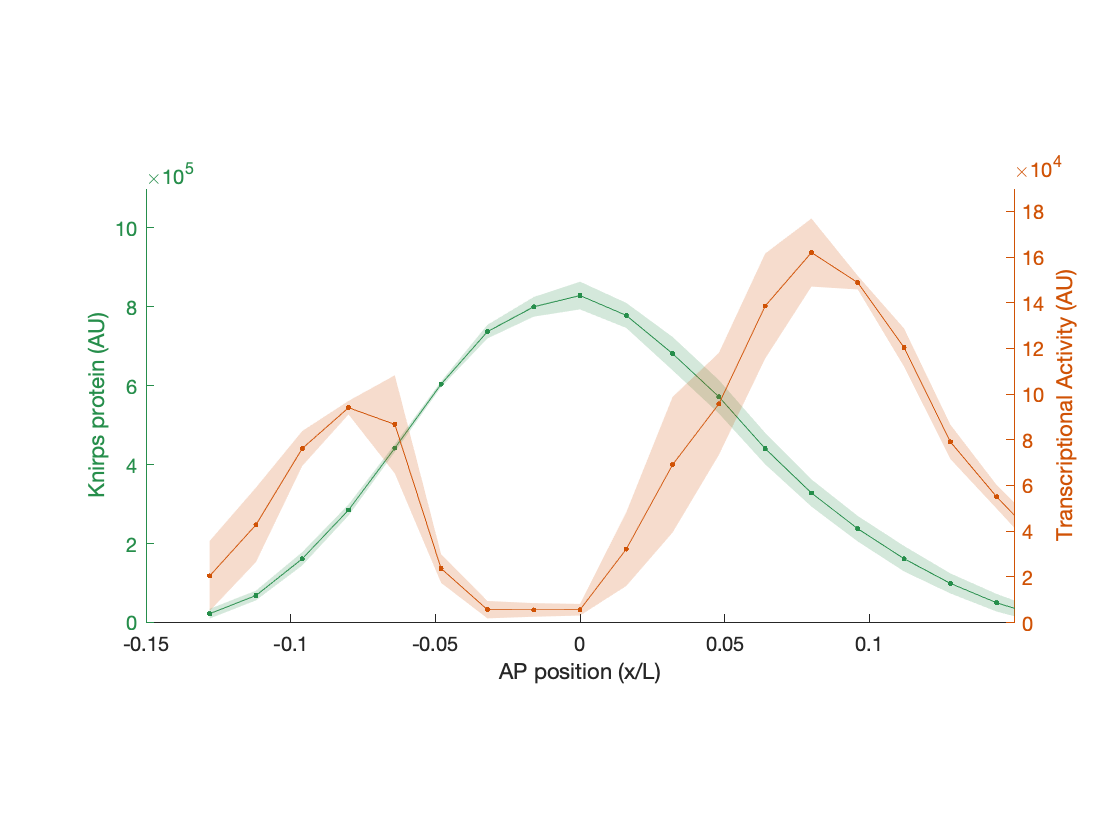

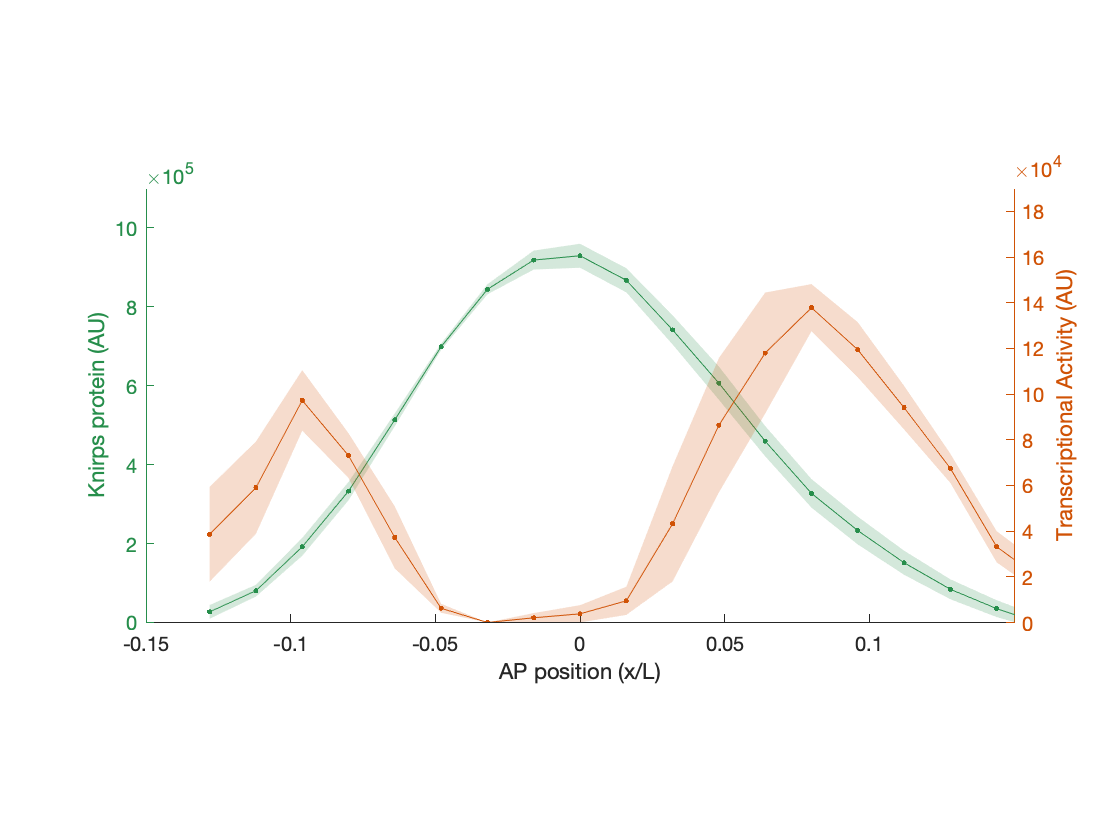

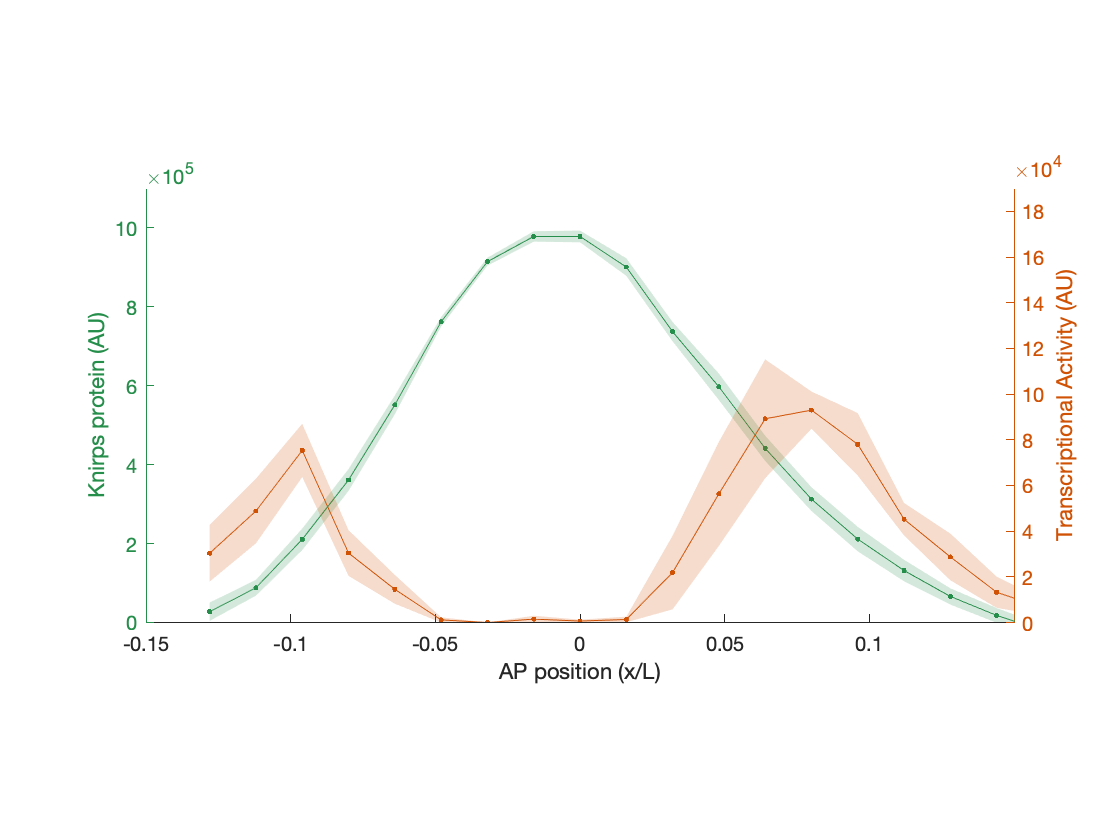

timeRange = [16 31 46 61 76, 91, 106];

for i = 1:length(timeRange)
    
    time_plot = timeRange(i);
    
    TimePlotFig = figure;  
    %protein_err_plot = [protein_err(bin_plot,:) ]
    set(TimePlotFig,'defaultAxesColorOrder',[left_color; right_color]);
    
    yyaxis left
    boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
    ylabel('Knirps protein (AU)')
    ylim([0 11E5])
    
    yyaxis right
    boundedline(binAP, spotFluoAPCombined(:,time_plot),spotFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', right_color);
    ylabel('Transcriptional Activity (AU)')
    ylim([0 1.9E5])
    
    pbaspect([2 1 1])
    xlabel('AP position (x/L)')
    xlim([-0.15 0.15])
end

## Plot time on and mean rate

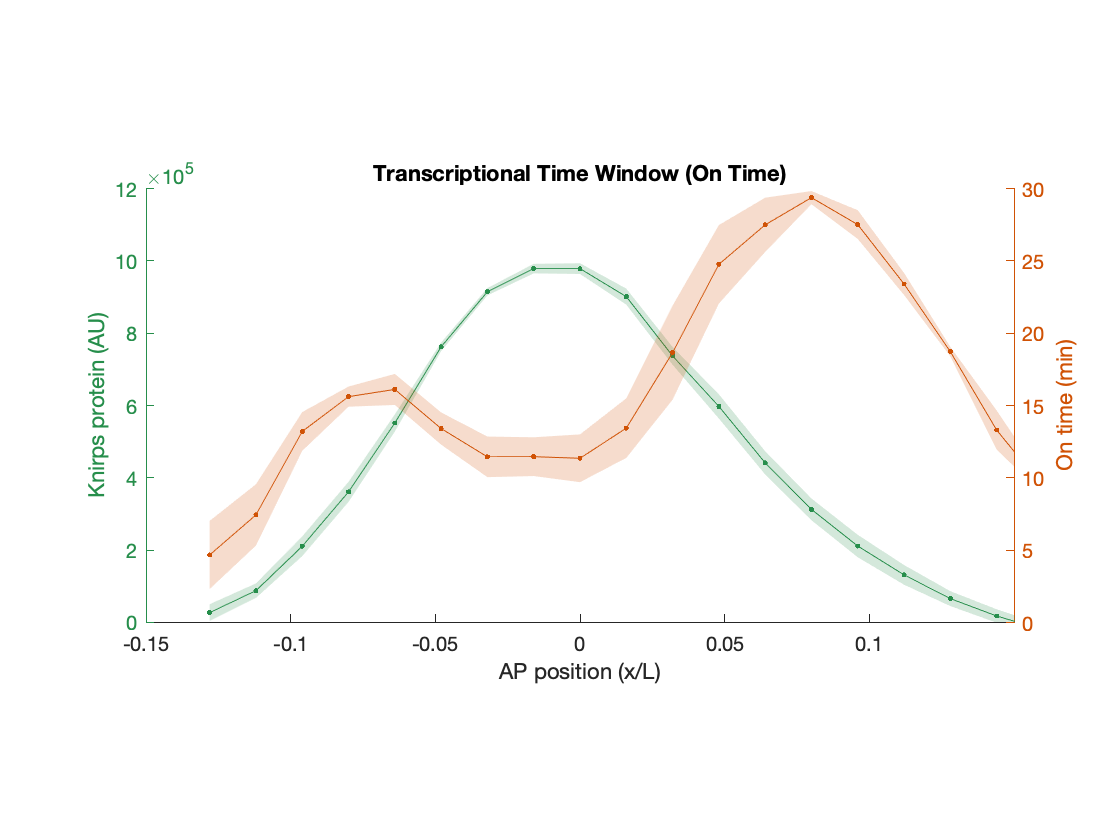

MeanRateFig = figure;

set(MeanRateFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAPCombined,timeOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 30])
ylabel('On time (min)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.15 0.15])
title('Transcriptional Time Window (On Time)')

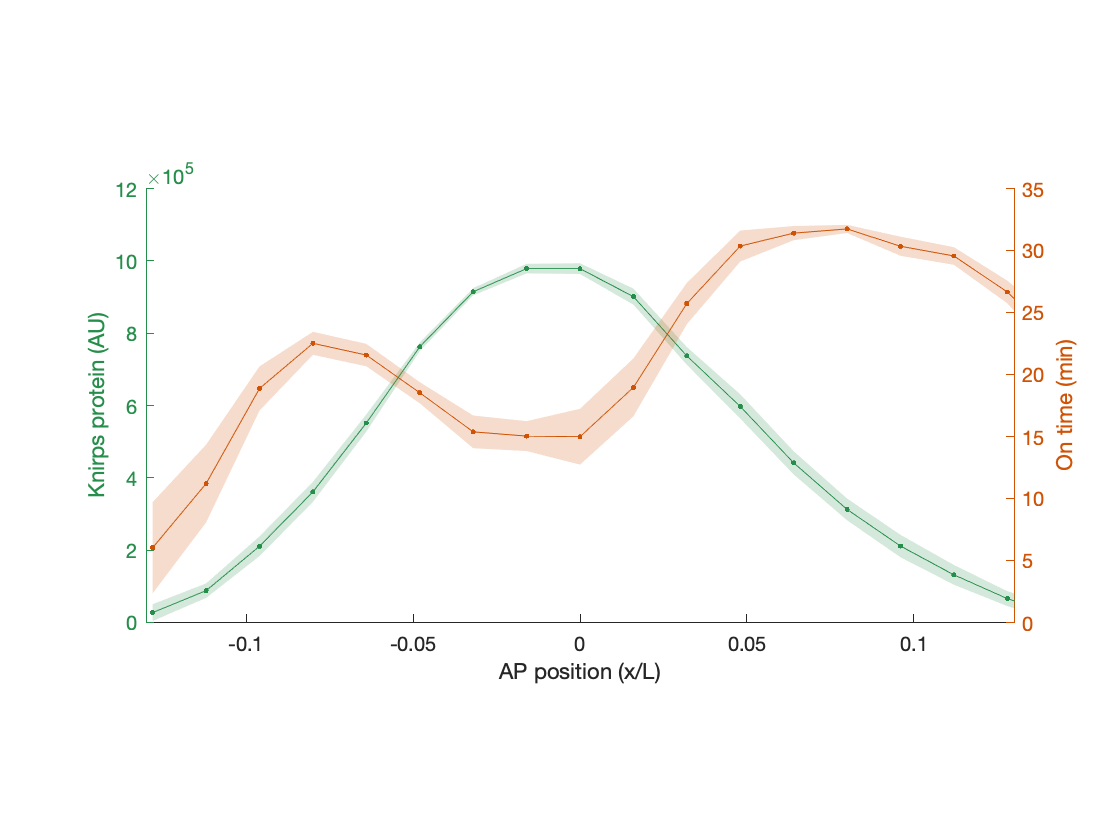


MeanRateAllFig = figure;

set(MeanRateAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAllAPCombined,timeOnAllAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 35])
ylabel('On time (min)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

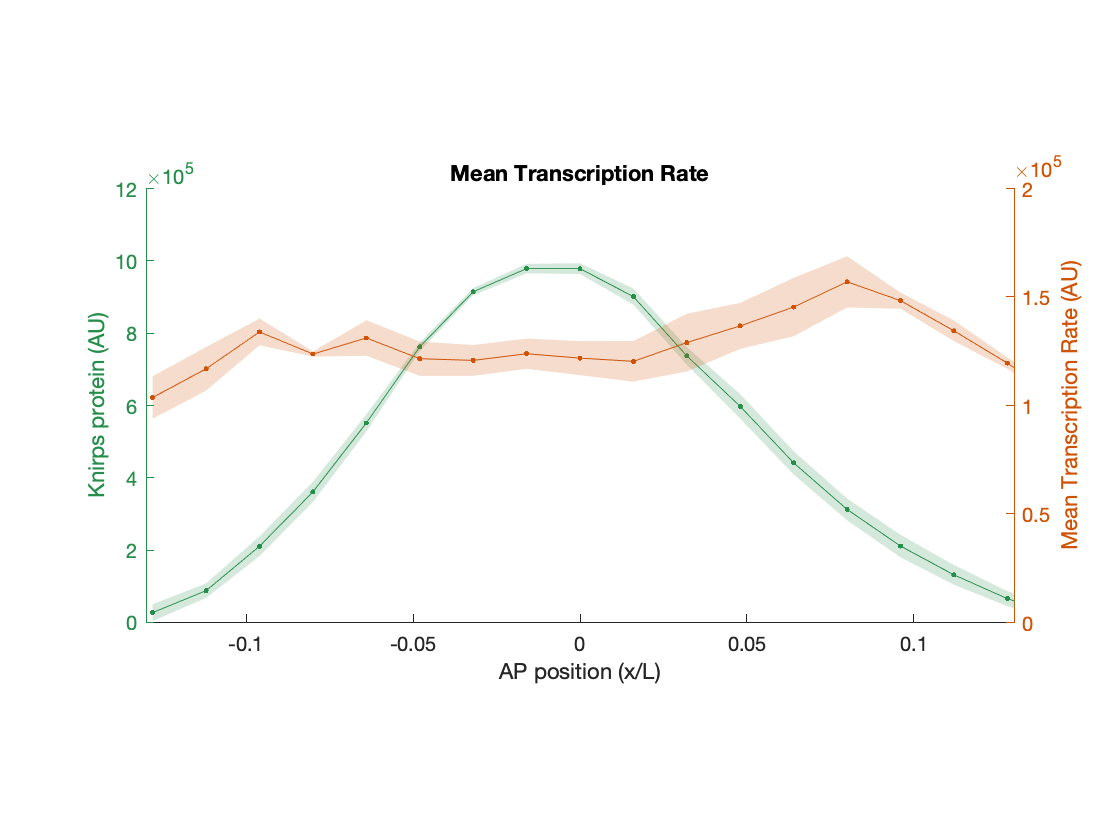


TimeOnFig = figure;
set(TimeOnFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, meanRateAPCombined,meanRateAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 2E5])
ylabel('Mean Transcription Rate (AU)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Mean Transcription Rate')

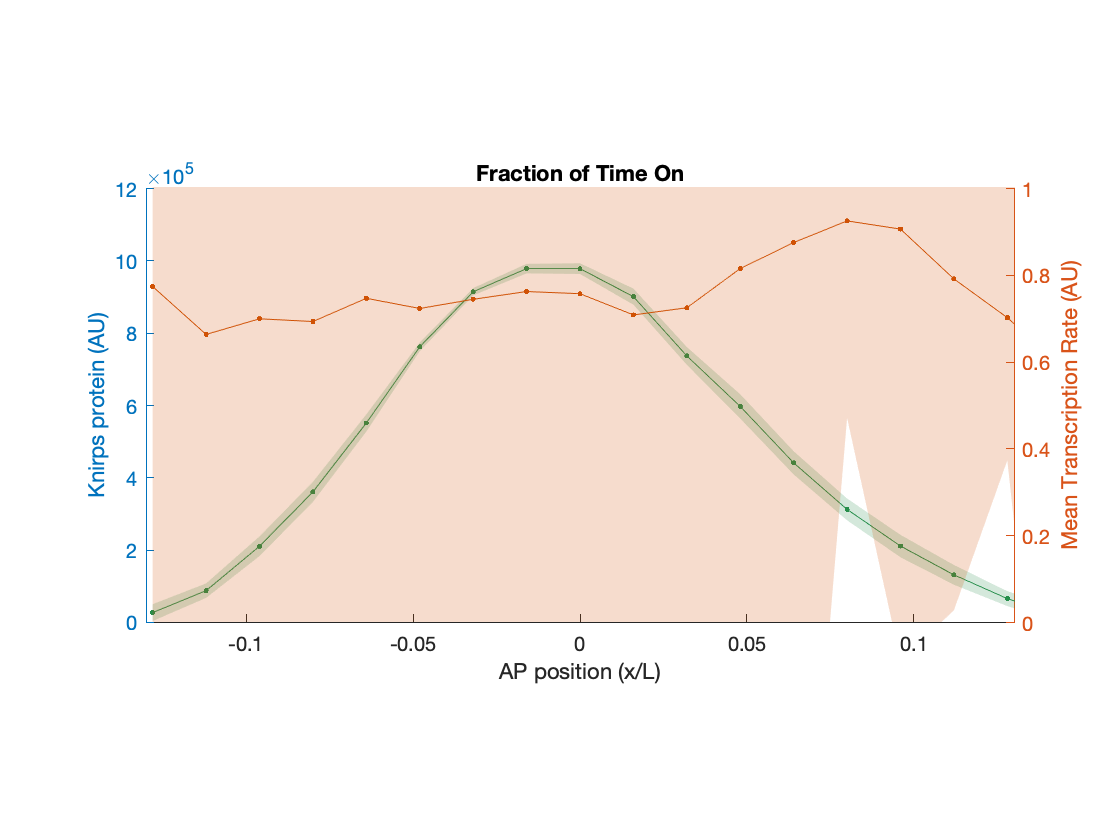

FractionOnFig = figure;
set(TimeOnFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAPCombined./timeOnAllAPCombined, timeOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 1])
ylabel('Mean Transcription Rate (AU)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Fraction of Time On')

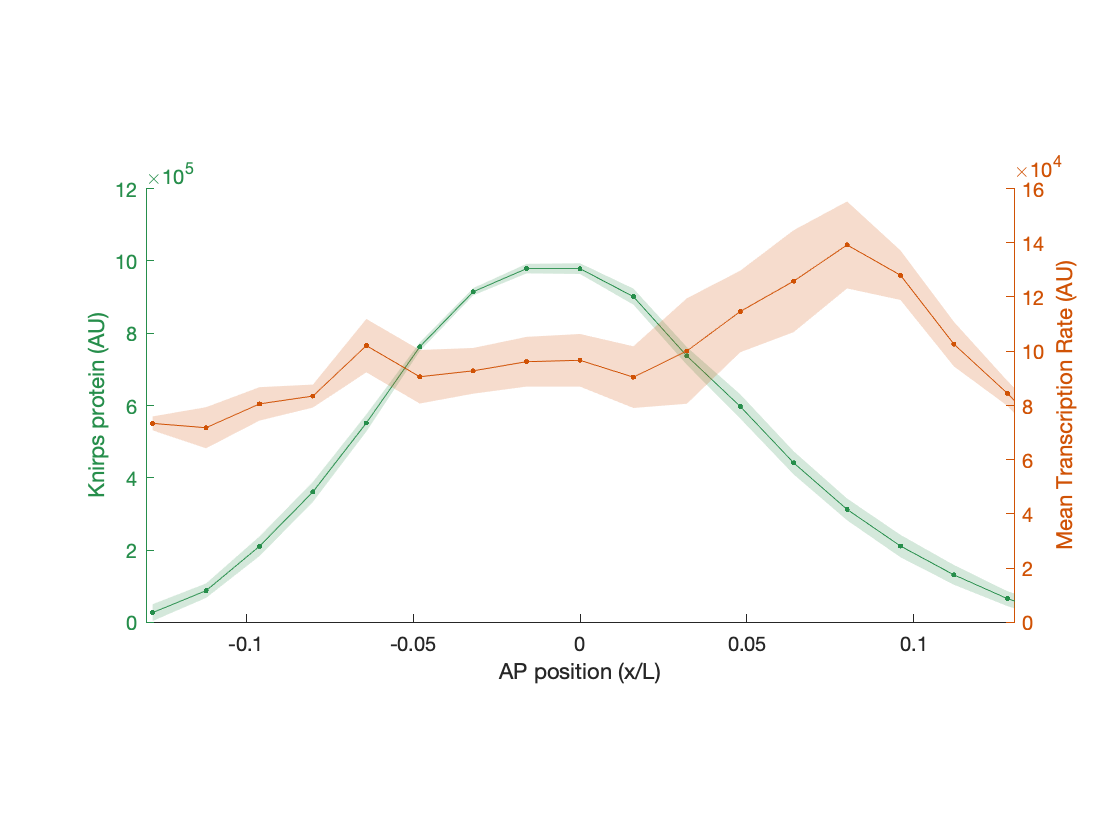


TimeOnAllFig = figure;
set(TimeOnAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, meanRateAllAPCombined,meanRateAllAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 1.6E5])
ylabel('Mean Transcription Rate (AU)')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

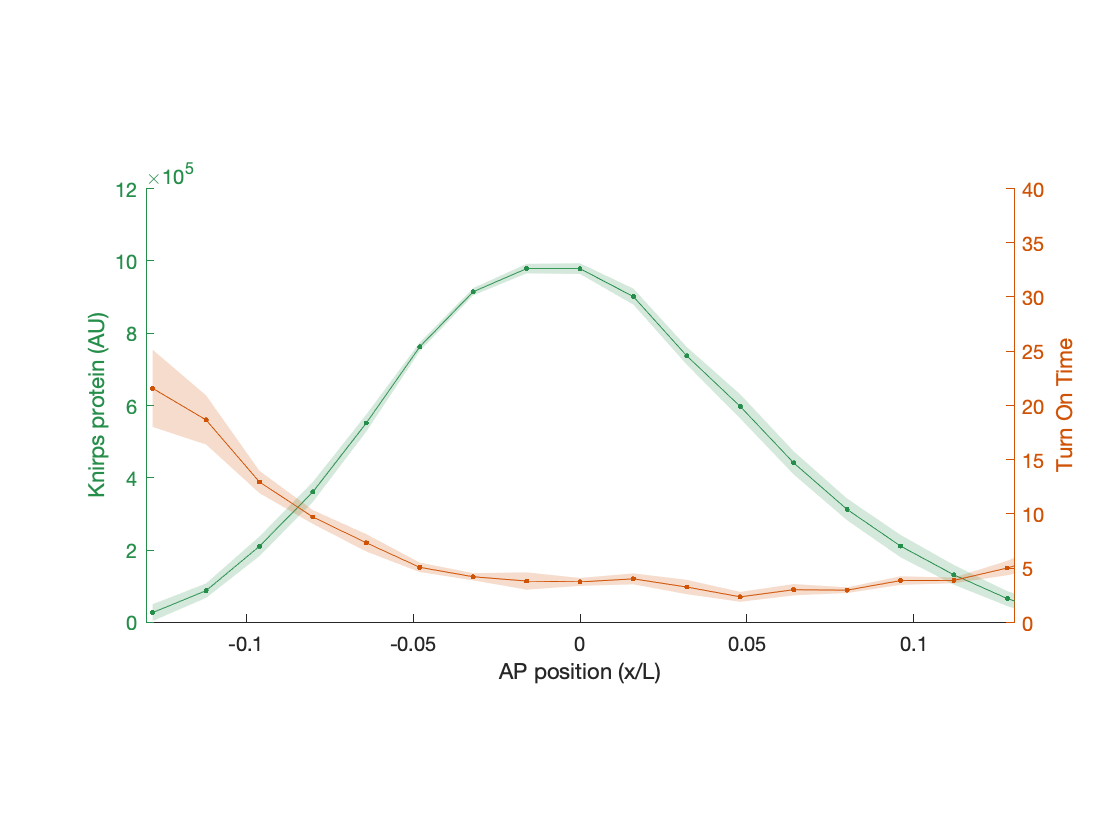


TurnOnAllFig = figure;
set(TurnOnAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, turnOnAPCombined,turnOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 40])
ylabel('Turn On Time')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

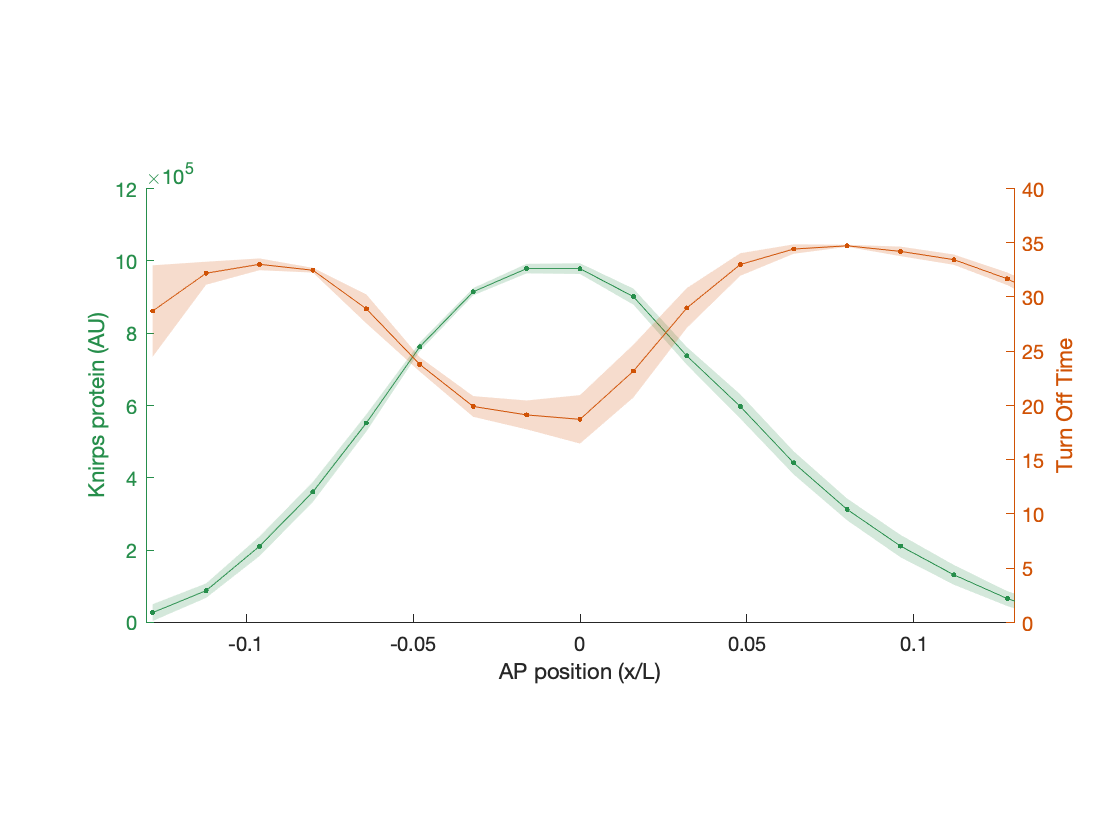


TurnOffAllFig = figure;
set(TurnOffAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, turnOffAPCombined,turnOffAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 40])
ylabel('Turn Off Time')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

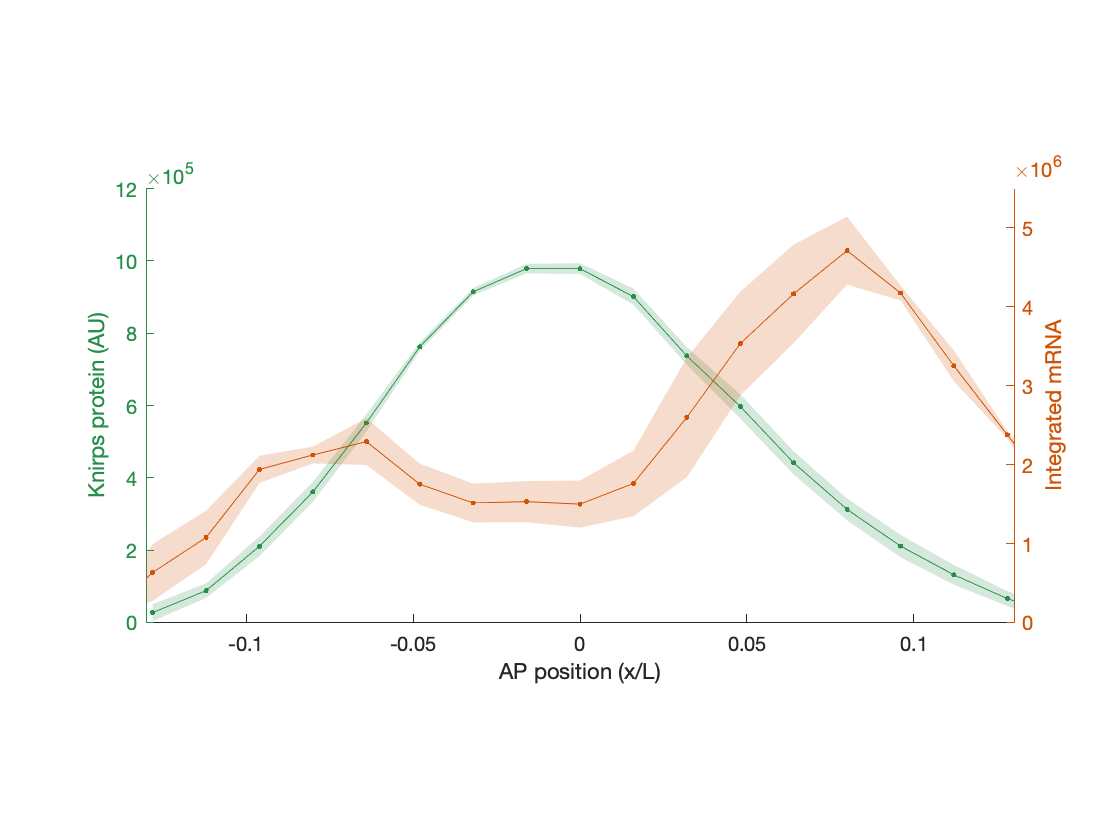


IntmRNAAllFig = figure;
set(IntmRNAAllFig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, intmRNAAPCombined,intmRNAAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 5.5E6])
ylabel('Integrated mRNA')
pbaspect([2 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])

### Comparison along AP axis

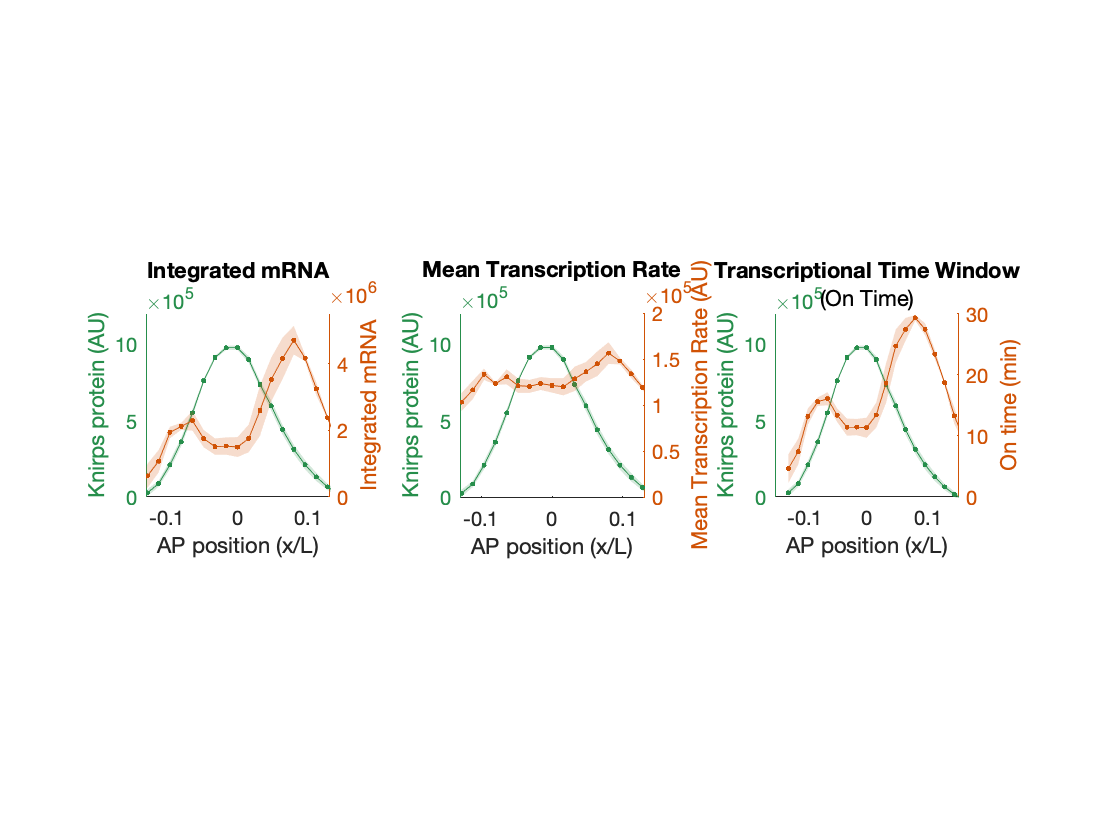

APComparisonFig = figure;
set(APComparisonFig,'defaultAxesColorOrder',[left_color; right_color]);

subplot(1,3,1)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, intmRNAAPCombined,intmRNAAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 5.5E6])
ylabel('Integrated mRNA')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Integrated mRNA',' ')

subplot(1,3,2)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, meanRateAPCombined,meanRateAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 2E5])
ylabel('Mean Transcription Rate (AU)')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Mean Transcription Rate',' ')

subplot(1,3,3)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAPCombined,timeOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 30])
ylabel('On time (min)')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.15 0.15])
title('Transcriptional Time Window','(On Time)')

### Time Window and On/Off Rate Comparision

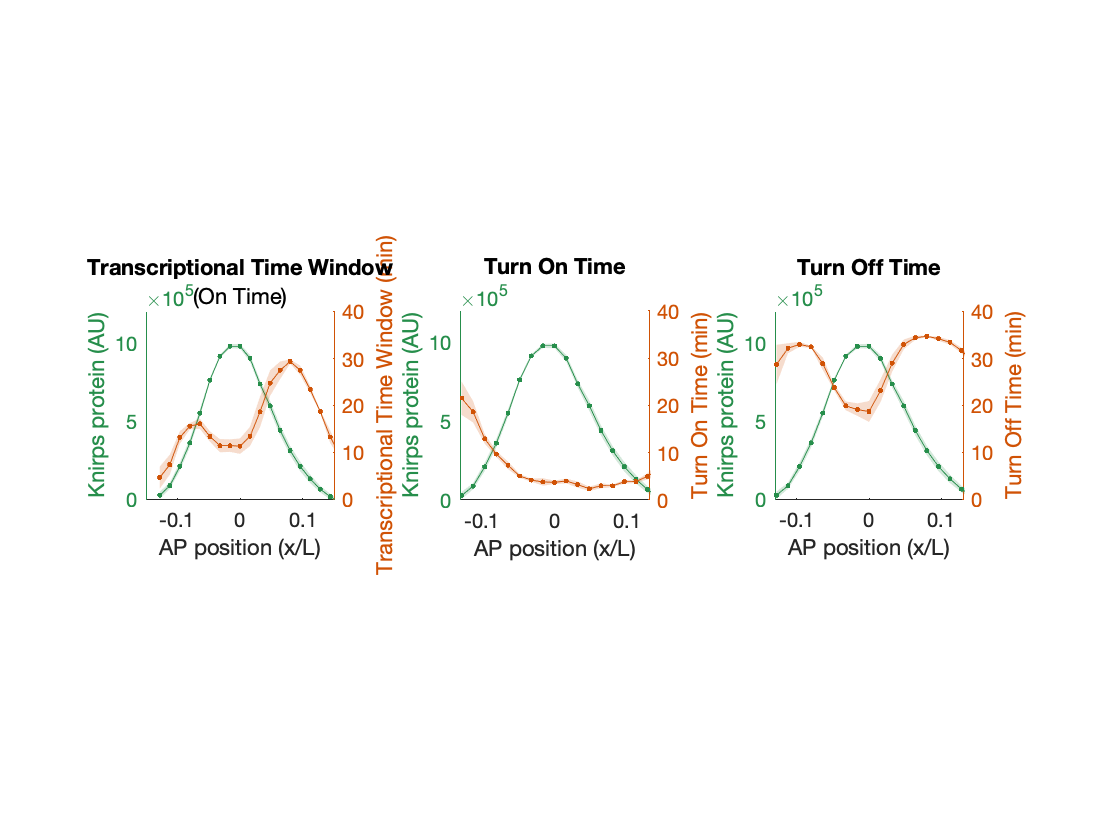

WindowComparisonFig = figure;
set(WindowComparisonFig,'defaultAxesColorOrder',[left_color; right_color]);

subplot(1,3,1)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, timeOnAPCombined,timeOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 40])
ylabel('Transcriptional Time Window (min)')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.15 0.15])
title('Transcriptional Time Window','(On Time)')

subplot(1,3,2)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, turnOnAPCombined,turnOnAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 40])
ylabel('Turn On Time (min)')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Turn On Time',' ')

subplot(1,3,3)
yyaxis left
boundedline(binAP, nuclearFluoAPCombined(:,time_plot),nuclearFluoAPErrCombined(:,time_plot), '- .','nan', 'gap','alpha','cmap', left_color);
ylabel('Knirps protein (AU)')
ylim([0 12E5])

yyaxis right
boundedline(binAP, turnOffAPCombined,turnOffAPErrCombined, '- .','nan', 'gap','alpha','cmap', right_color);
ylim([0 40])
ylabel('Turn Off Time (min)')
pbaspect([1 1 1])
xlabel('AP position (x/L)')
xlim([-0.13 0.13])
title('Turn Off Time',' ')

## Part 3: Input-output functions

### Comparison of input-output functions

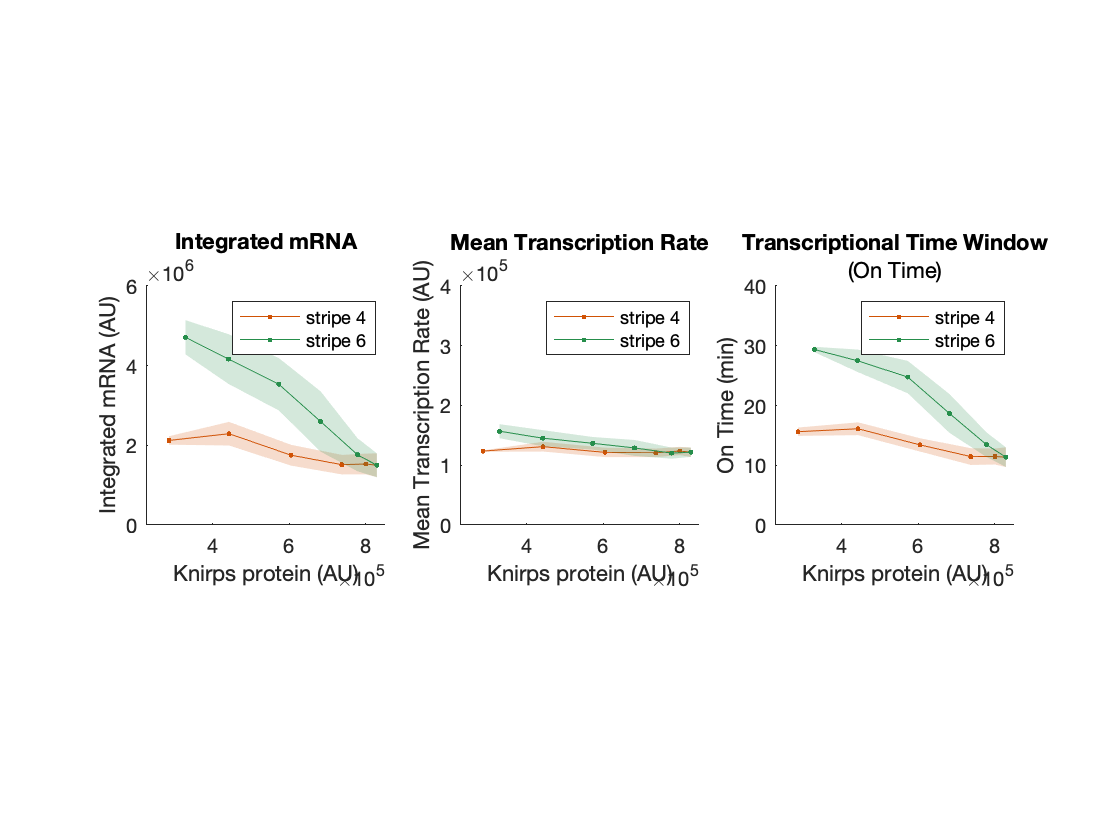

PatternIOFig = figure;
subplot(1,3,1)
AP_range_stripe6 = 13:18;
AP_range_stripe4 = 8:13;
time_plot = 76;

%boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPErrCombined(AP_range_stripe4,time_plot),'- .','nan', 'gap','alpha','cmap', right_color);
p1 = boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),intmRNAAPCombined(AP_range_stripe4),intmRNAAPErrCombined(AP_range_stripe4),'- .','nan', 'gap','alpha','cmap', right_color);
hold on
%boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPErrCombined(AP_range_stripe6,time_plot),'- .','nan', 'gap','alpha','cmap', left_color);
p2 = boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),intmRNAAPCombined(AP_range_stripe6),intmRNAAPErrCombined(AP_range_stripe6),'- .','nan', 'gap','alpha','cmap', left_color);

xlim([2.25E5 8.5E5])
ylim([0E5 6E6])
xlabel('Knirps protein (AU)')
ylabel('Integrated mRNA (AU)')
legend([p1, p2],'stripe 4','stripe 6')
pbaspect([1 1 1])
title('Integrated mRNA',' ')

subplot(1,3,2)
p1 = boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),meanRateAPCombined(AP_range_stripe4),meanRateAPErrCombined(AP_range_stripe4),'- .','nan', 'gap','alpha','cmap', right_color);
hold on
p2 = boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),meanRateAPCombined(AP_range_stripe6),meanRateAPErrCombined(AP_range_stripe6),'- .','nan', 'gap','alpha','cmap', left_color);

xlim([2.25E5 8.5E5])
ylim([0E5 4E5])
xlabel('Knirps protein (AU)')
ylabel('Mean Transcription Rate (AU)')
legend([p1, p2],'stripe 4','stripe 6')
pbaspect([1 1 1])

title('Mean Transcription Rate',' ')

subplot(1,3,3)
p1 = boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),timeOnAPCombined(AP_range_stripe4),timeOnAPErrCombined(AP_range_stripe4), '- .','nan', 'gap','alpha','cmap', right_color);
hold on
p2 = boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),timeOnAPCombined(AP_range_stripe6),timeOnAPErrCombined(AP_range_stripe6), '- .','nan', 'gap','alpha','cmap', left_color);

xlim([2.25E5 8.5E5])
ylim([0 40])
xlabel('Knirps protein (AU)')
ylabel('On Time (min)')
legend([p1, p2],'stripe 4','stripe 6')
pbaspect([1 1 1])
title('Transcriptional Time Window','(On Time)')

### Comparison of timeOn/Off

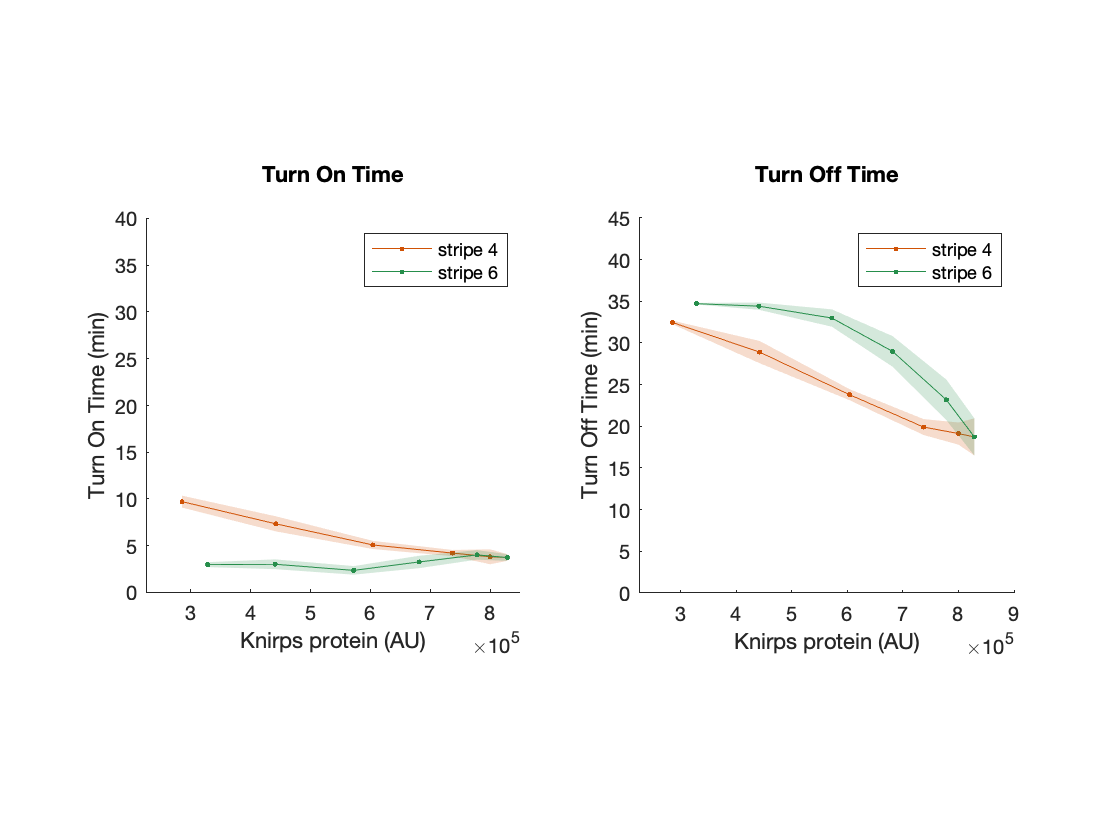

TimeOnOffFig = figure;
subplot(1,2,1)
AP_range_stripe6 = 13:18;
AP_range_stripe4 = 8:13;
time_plot = 76;

%boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPErrCombined(AP_range_stripe4,time_plot),'- .','nan', 'gap','alpha','cmap', right_color);
p1 = boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),turnOnAPCombined(AP_range_stripe4),turnOnAPErrCombined(AP_range_stripe4),'- .','nan', 'gap','alpha','cmap', right_color);
hold on
%boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPErrCombined(AP_range_stripe6,time_plot),'- .','nan', 'gap','alpha','cmap', left_color);
p2 = boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),turnOnAPCombined(AP_range_stripe6),turnOnAPErrCombined(AP_range_stripe6),'- .','nan', 'gap','alpha','cmap', left_color);

xlim([2.25E5 8.5E5])
ylim([0 40])
xlabel('Knirps protein (AU)')
ylabel(['Turn On Time (min)'])
legend([p1, p2],'stripe 4','stripe 6')
pbaspect([1 1 1])
title('Turn On Time',' ')
subplot(1,2,2)
AP_range_stripe6 = 13:18;
AP_range_stripe4 = 8:13;
time_plot = 76;
%time_plot = 100;

%boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPCombined(AP_range_stripe4,time_plot),spotFluoAPErrCombined(AP_range_stripe4,time_plot),'- .','nan', 'gap','alpha','cmap', right_color);
p1 = boundedline(nuclearFluoAPCombined(AP_range_stripe4,time_plot),turnOffAPCombined(AP_range_stripe4),turnOffAPErrCombined(AP_range_stripe4),'- .','nan', 'gap','alpha','cmap', right_color);
hold on
%boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPCombined(AP_range_stripe6,time_plot),spotFluoAPErrCombined(AP_range_stripe6,time_plot),'- .','nan', 'gap','alpha','cmap', left_color);
p2 = boundedline(nuclearFluoAPCombined(AP_range_stripe6,time_plot),turnOffAPCombined(AP_range_stripe6),turnOffAPErrCombined(AP_range_stripe6),'- .','nan', 'gap','alpha','cmap', left_color);

xlim([2.25E5 9E5])
ylim([0 45])
xlabel('Knirps protein (AU)')
ylabel('Turn Off Time (min)')
legend([p1, p2],'stripe 4','stripe 6')
pbaspect([1 1 1])
title('Turn Off Time',' ')